# Matpower Simulation

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a 33 bus feeder - source here: [https://egriddata.org/dataset/33-bus-radial-distribution-system](https://egriddata.org/dataset/33-bus-radial-distribution-system) 

clear all
close all
clc
addpath('./src/');
rng(11);

We load the data.

define_constants;
mpc = loadcase('case4gs');

We define useful constants and we derive the impedence matrix.

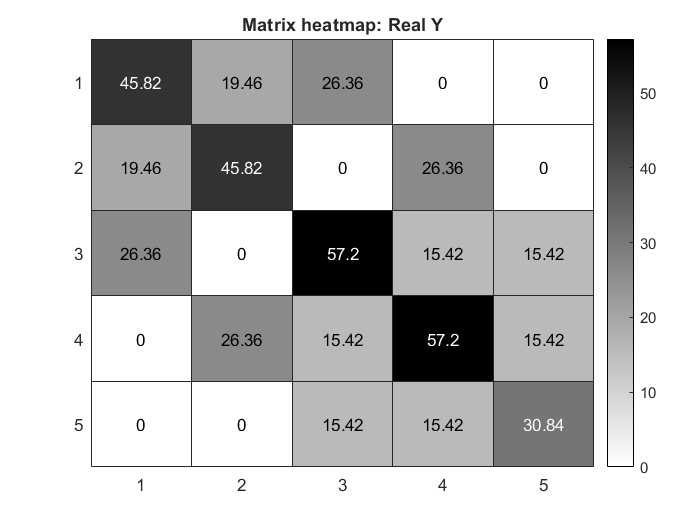

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))

ans = 8.8818e-16 + 3.5527e-15i

issymmetric(Y)

ans = logical
   1


Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles. [TODO]

samples = 200;
load_avg_pd = mpc.bus(load_mask, PD);
load_avg_qd = mpc.bus(load_mask, QD);
for i = 1:samples
    mpc.bus(load_mask, PD) = normrnd(load_avg_pd, 0.05 * load_avg_pd);
    mpc.bus(load_mask, QD) = normrnd(load_avg_qd, 0.05 * load_avg_qd);
    res = runpf(mpc);
    bus_phase = res.bus(:, VA) * pi / 180;
    bus_magnitude = res.bus(:, VM);
    bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
    load_pd(:, i) = res.bus(load_mask, PD);
    load_qd(:, i) = res.bus(load_mask, QD);
end


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 4 iterations.

Converged in 0.07 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              5     Total Gen Capacity     636.0        -300.0 to 300.0
Generators         3     On-line Capacity       636.0        -300.0 to 300.0
Committed Gens     3     Generation (actual)    572.4             435.1
Loads              5     Load                   558.7             366.5
  Fixed            5       Fixed                558.7             366.5
  Dispatchable     0       Dispatchable          -0.0 of -0.0     

bus_current = Y * bus_voltage;

Randomly generated voltages and currents for testing purpose only.

% bus_voltage = normrnd(100, 5, [n, samples]) + sqrt(-1) * normrnd(100, 5, [n, samples]);
% bus_current = Y * bus_voltage;

We visualize the evolution of the voltage and the current for a random node.

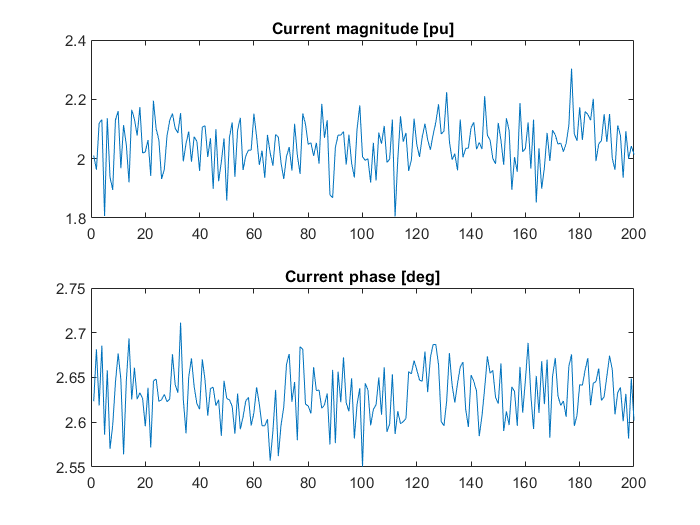

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title('Current magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title('Current phase [deg]');

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_voltage));
title('Voltage magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_voltage));

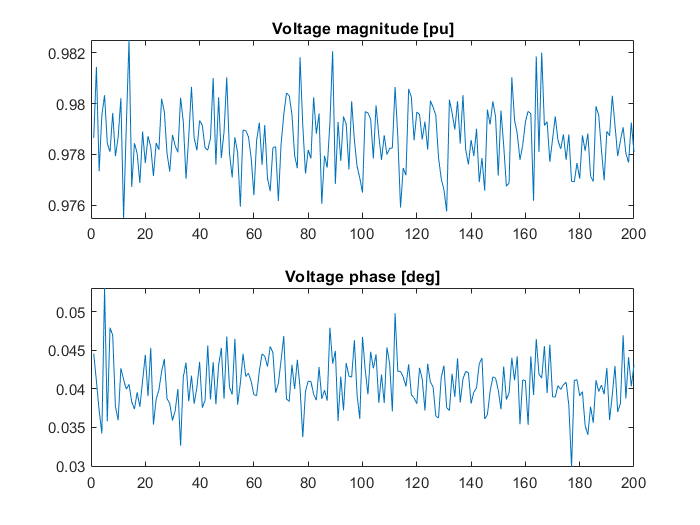

title('Voltage phase [deg]');

## Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

## OLS estimation

As a first benchmark, we estimate the admittance matrix using Ordinary Least.

Froebius norm for OLS is 7.9144e-11
Max norm for OLS is 3.8096e-11


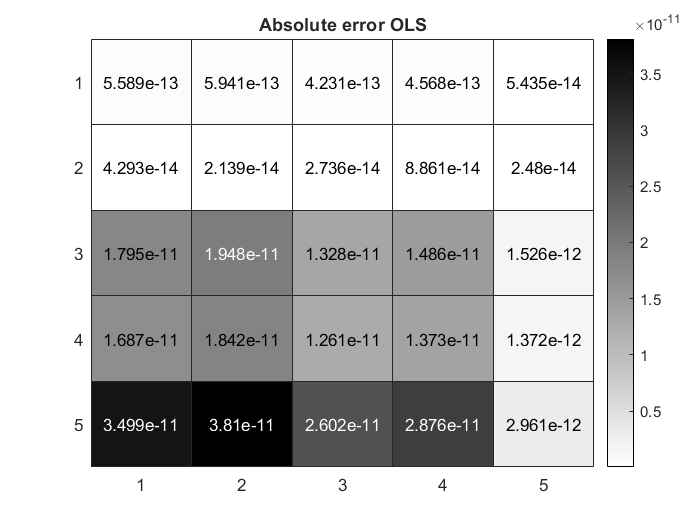

Y_hat_ols = conj(bus_voltage' \ bus_current');
error_metrics(Y, Y_hat_ols, 'OLS');

## Lasso Estimation

Following Ardakanian et al, we now resort to Lasso in order to peform the same estimation.

idx = 1:n;
nidx = setdiff(1:n,idx);
[Y22_est, Y12_est, Y11_est] = postprocessing(bus_voltage,bus_current,idx,nidx,Y);

Lasso method is being used...
best lambda is 0.0001
maximum absolute error is 7.0492e-05
error norm is 0.00029051
no. nonzero elements: 17
Thresholded lasso method with refitting is being used...
best lambda is 0.0001
maximum absolute error is 1.4862e-11
error norm is 2.8729e-11
no. nonzero elements: 17
Adaptive lasso method with OLS based weights is being used...
optimal gamma is 2
best lambda is 0.0001
maximum absolute error is 1.9544e-06
error norm is 5.3003e-06
no. nonzero elements: 17
Thresholded lasso with refitting outperformed other methods
Relative error (pct): 9.6396e-11


Froebius norm for Lasso is 2.8729e-11
Max norm for Lasso is 1.4862e-11


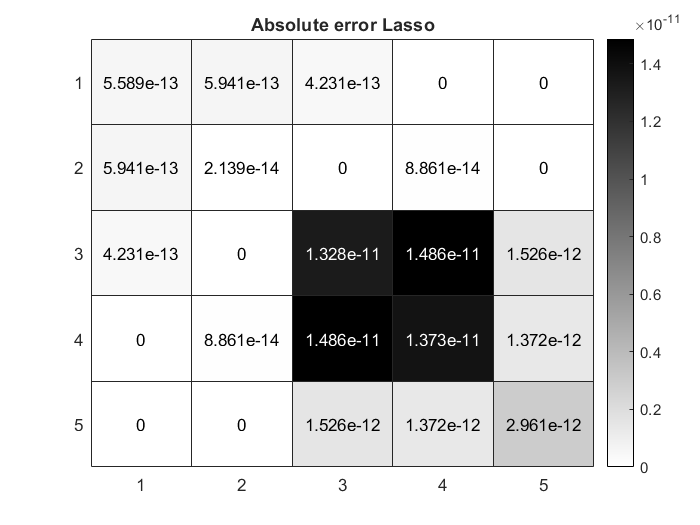

Y_hat_lasso  = [Y11_est Y12_est; Y12_est.' Y22_est];
error_metrics(Y, Y_hat_lasso, 'Lasso');

## RLS with symmetricity constraints (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

Froebius norm for RLS1 is 3.3251e-11
Max norm for RLS1 is 2.2803e-11


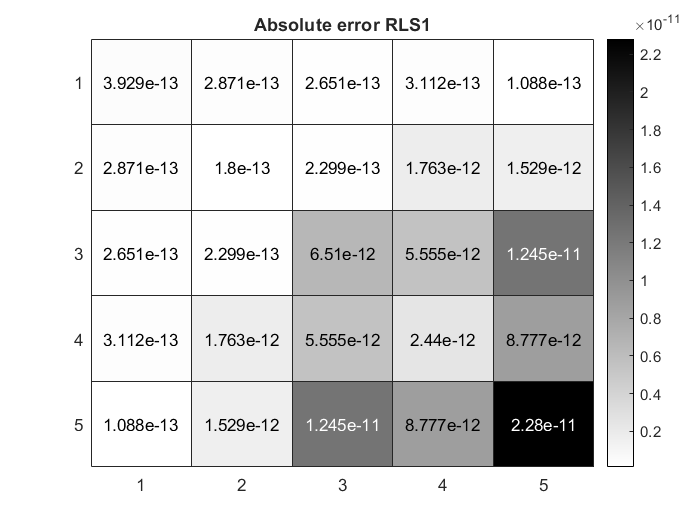

lambda = 0.8;
D = duplication_matrix(n);
[Y1_hat, Z1_hat] = estimate_rls(bus_voltage, bus_current, D, lambda);
error_metrics(Y, Y1_hat(:, :, end), 'RLS1');

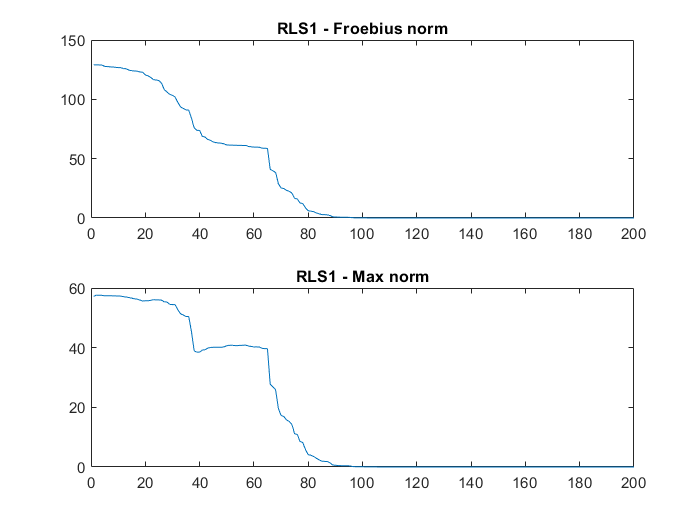

error_evolution(Y, Y1_hat, 'RLS1');

## RLS2

Then, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

Froebius norm for RLS2 is 2.5172e-12
Max norm for RLS2 is 1.7805e-12


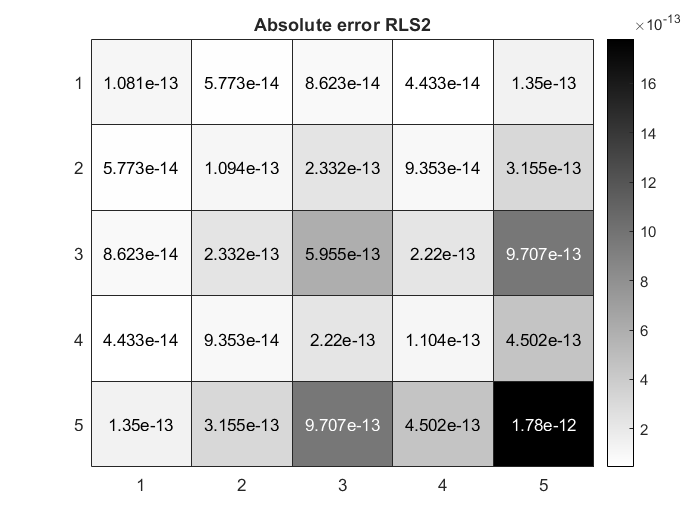

rls2_free_params = n*(n-1)/2;
Q = D * transformation_matrix(n);
[Y2_hat, Z2_hat] = estimate_rls(bus_voltage, bus_current, Q, lambda);
error_metrics(Y, Y2_hat(:, :, end), 'RLS2');

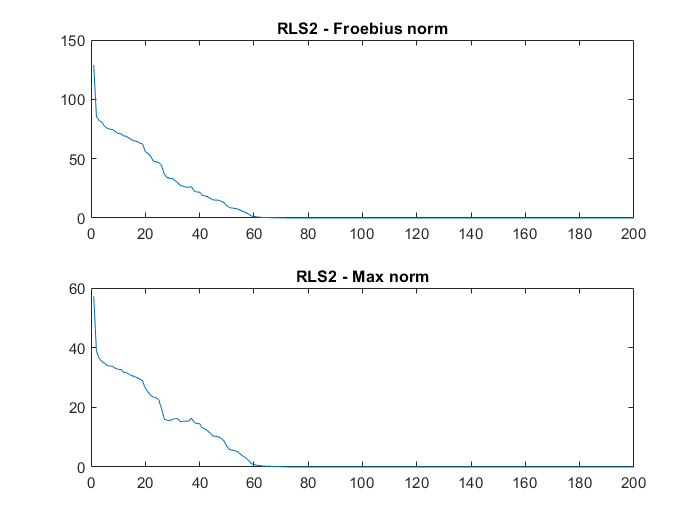

error_evolution(Y, Y2_hat, 'RLS2');

## RLS with DoE